# Run analyzePRF on an example dataset to fit the whole time series

clear; close all; setup;


% Repeating this experiment using the data from BCBL

## Load in the data

% Load in the data
load('exampledataset.mat');
% Load the BCBL data in paralel, all variables same name ended in bcbl
databcbl{1} = MRIread('~/soft/PRF/local/sub-23MAGNO6134T2/fmriprep/sub-23MAGNO6134/ses-T2/func/sub-23MAGNO6134_ses-T2_task-ret_run-01_space-fsnative_hemi-L.func_REGRESSED.mgh');
databcbl{2} = MRIread('~/soft/PRF/local/sub-23MAGNO6134T2/fmriprep/sub-23MAGNO6134/ses-T2/func/sub-23MAGNO6134_ses-T2_task-ret_run-02_space-fsnative_hemi-L.func_REGRESSED.mgh');
databcbl{3} = MRIread('~/soft/PRF/local/sub-23MAGNO6134T2/fmriprep/sub-23MAGNO6134/ses-T2/func/sub-23MAGNO6134_ses-T2_task-ret_run-03_space-fsnative_hemi-L.func_REGRESSED.mgh');
% Select 10 voxels as they do
vtxList = [2883:2892];
databcbl{1} = squeeze(databcbl{1}.vol(1,vtxList+1,:,5:end));
databcbl{2} = squeeze(databcbl{2}.vol(1,vtxList+1,:,5:end));
databcbl{3} = squeeze(databcbl{3}.vol(1,vtxList+1,:,5:end));

% fMRIprep gives us the regresors, but it doesn' clean it
% use AFNI:3dTproject, nilearn, or see if I can do it in Matlab



% Check the workspace
whos

  Name          Size               Bytes  Class     Attributes

  data          1x4                24448  cell                
  databcbl      1x3                38976  cell                
  source        1x2                  416  cell                
  stimulus      1x4             48000448  cell                
  vtxList       1x10                  80  double              



## Inspect the data

% Check dimensionality of the data
data

data = 1×4 cell array
    {10×150 single}    {10×150 single}    {10×150 single}    {10×150 single}


databcbl

databcbl = 1×3 cell array
    {10×161 double}    {10×161 double}    {10×161 double}


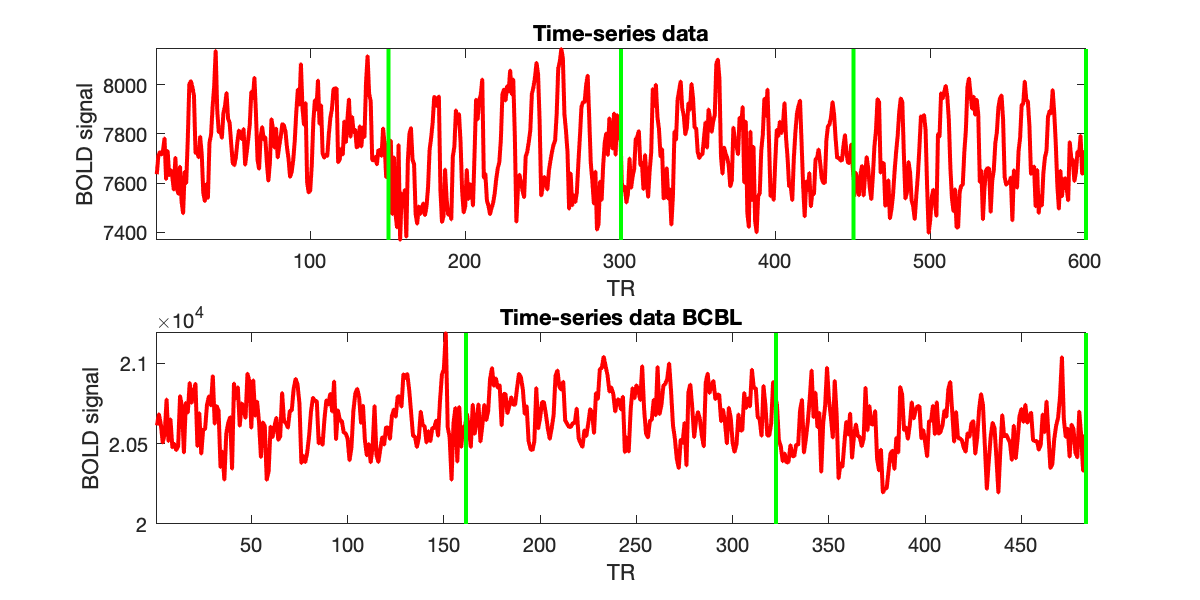

% There are four runs of data; each run consists of 150 time points (TR = 2 s).
% The data have already been pre-processed for slice timing correction, motion
% correction, and spatial undistortion.  For simplicity, we have selected
% 10 example voxels from the left hemisphere.  Let's visualize the time-series
% data for the second voxel.
temp = cellfun(@(x) x(2,:),data,'UniformOutput',0);
tempbcbl = cellfun(@(x) x(6,:),databcbl,'UniformOutput',0);

figure; hold on;
set(gcf,'Units','points','Position',[100 100 600 300]);
subplot(2,1,1)
plot(cat(2,temp{:}),'r-');
straightline(150*(1:4)+.5,'v','g-');
xlabel('TR');
ylabel('BOLD signal');
ax = axis;
axis([.5 600+.5 ax(3:4)]);
title('Time-series data');

subplot(2,1,2)
plot(cat(2,tempbcbl{:}),'r-');
straightline(161*(1:3)+.5,'v','g-');
xlabel('TR');
ylabel('BOLD signal');
ax = axis;
axis([.5 161*3+.5 ax(3:4)]);
title('Time-series data BCBL');

## Inspect the stimuli

% Check dimensionality of the stimuli
stimulus

stimulus = 1×4 cell array
    {100×100×300 single}    {100×100×300 single}    {100×100×300 single}    {100×100×300 single}


% Read the mask images (the apertures, they saw words inside the apertures)
% This file is the same for everybody
BAR = load('~/soft/PRF/local/sub-23MAGNO6134T2/stimuli/maskimages.mat');
images = BAR.maskimages;

% Load bcbl stimuli
stimFileBcbl{1} = load('~/soft/PRF/local/sub-23MAGNO6134T2/stimuli/subj6134_T2_run1_exp103.mat');
stimFileBcbl{2} = load('~/soft/PRF/local/sub-23MAGNO6134T2/stimuli/subj6134_T2_run2_exp103.mat');
stimFileBcbl{3} = load('~/soft/PRF/local/sub-23MAGNO6134T2/stimuli/subj6134_T2_run3_exp103.mat');

for ns=1:length(stimFileBcbl)
    % And how many images from the beginning will be discarded
    params{ns}.removeImagesN   = 4;
    % Maddi se aseguro de que termine bien, por lo tanto, esto dura: 161 * 1.82 segundos
    params{ns}.scanDuration = 300;
    params{ns}.totalScans   = 165;
    params{ns}.tr           = 1.82;
    config{ns}.config.rescaleStimuliImages = true;
    config{ns}.config.imageSideSize = 100;  
    
    
    % Every 1.82 an image was acquired, and every 1.82 seconds a different image
    % was shown. Select the image that was shown every 1.82. We know that the
    % response is later, though
    
    % Create the 2D+time dataset of stimulus images over TRs.
    % We need to sub-sample to have the same number of images as the fMRI timepoints
    % Create the image index that will select the images shown when the acquisition
    % took place. Do step by step for clarity:
%     imIndx{ns} = stimFileBcbl{ns}.frameorder(2,:);
%     imIndx{ns} = imIndx{ns}(imagesPerSecond{ns}:imagesPerSecond{ns}:4500);
%     imIndx{ns} = imIndx{ns}(params{ns}.tr:params{ns}.tr:params{ns}.scanDuration+1);
%     imIndx{ns} = imIndx{ns}((params{ns}.removeImagesN + 1):params{ns}.totalScans);
%     imIndx{ns}(imIndx{ns}==0)=1;

    % This is what has been shown
    allImgRefs = stimFileBcbl{ns}.frameorder(2,:);
    % Every tr=1.82 an image has been showns, what is the index of this image?
    % We need to obtain 161 indices, and selected the corresponding number from
    % the existing 4500 images. 
    tmpInd = round(1:length(allImgRefs)/params{ns}.totalScans:length(allImgRefs));
    % Remove the images that correspond to the acquisitions we removed
    ImgRefs = allImgRefs(tmpInd((params{ns}.removeImagesN + 1):end));
    % ImgRefs(ImgRefs==0)=1;
   
    % Create the new trAdjImages stimuli set
    trAdjImages{ns} = zeros([size(images,1),size(images,2),size(ImgRefs,2)]);
    trAdjImages{ns}(:,:,ImgRefs~=0) = images(:,:,ImgRefs(ImgRefs~=0));
    
    temp = zeros(config{ns}.config.imageSideSize, config{ns}.config.imageSideSize, size(stimFileBcbl,3));
    for p=1:size(trAdjImages{ns}, 3)
        temp(:,:,p) = imresize(trAdjImages{ns}(:,:,p),[config{ns}.config.imageSideSize config{ns}.config.imageSideSize],'cubic');
    end
    trAdjImages{ns} = temp;

    % ensure that all values are between 0 and 1
    trAdjImages{ns}(trAdjImages{ns} < 0) = 0;
    trAdjImages{ns}(trAdjImages{ns} > 1) = 1;
 
end
stimulusbcbl = trAdjImages;


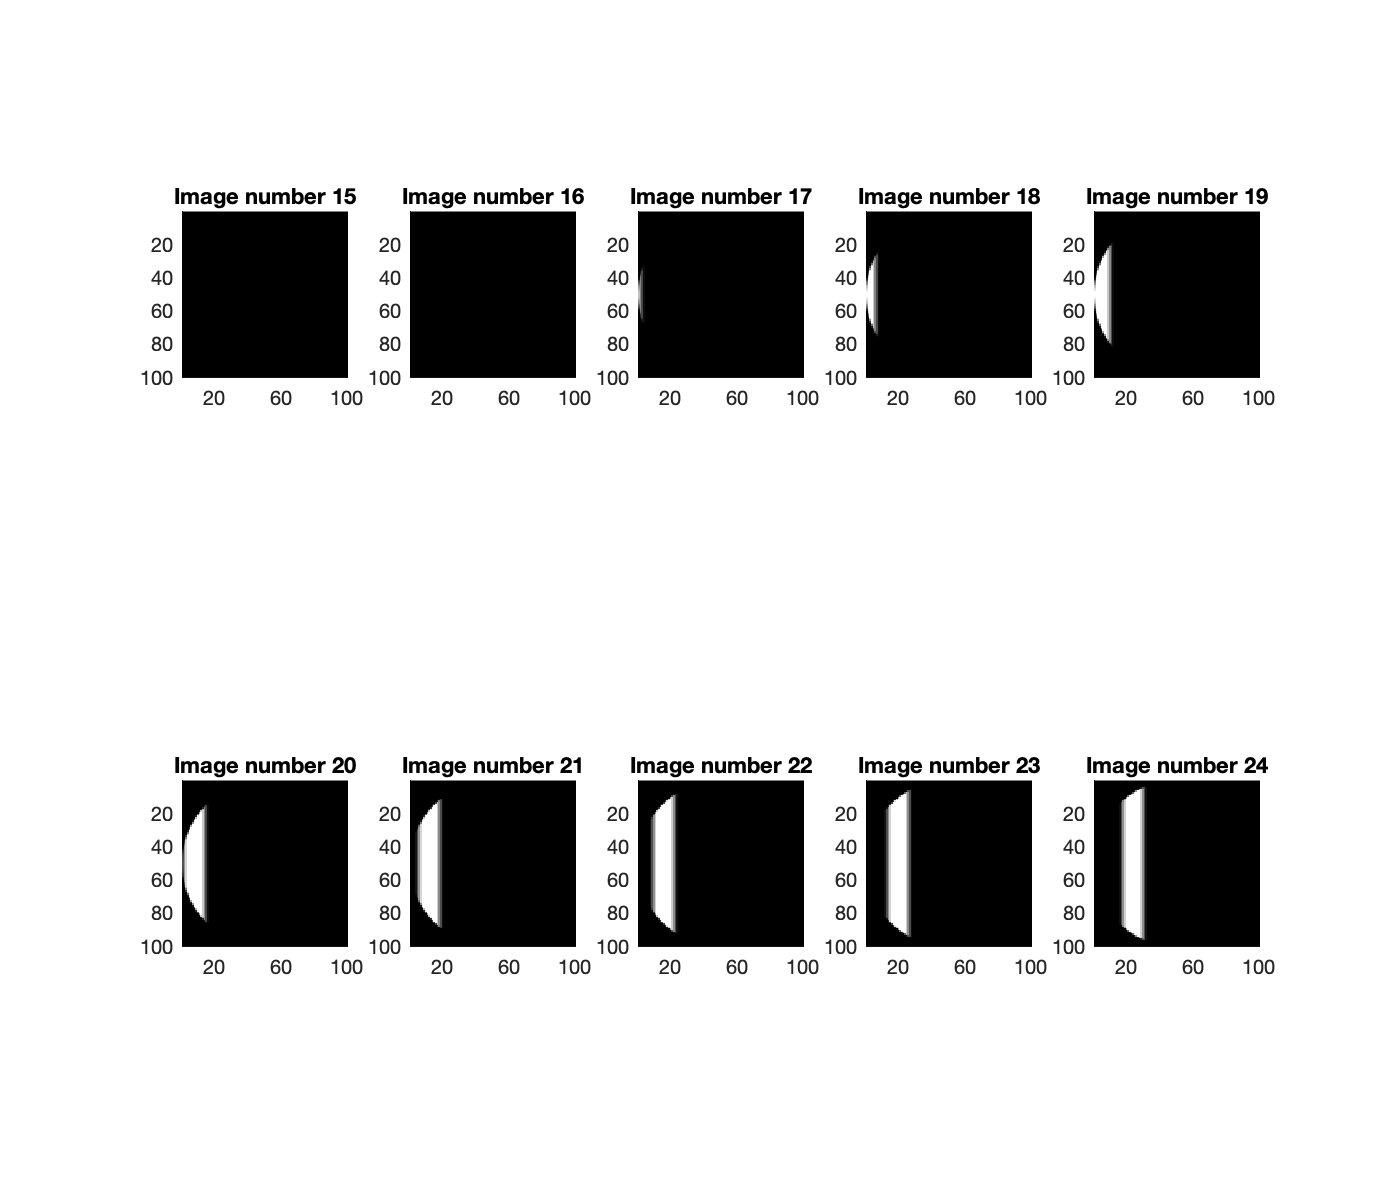

% The stimulus images have been prepared at a resolution of 100 pixels x 100 pixels.
% There are 300 images per run because we have prepared the images at a time resolution
% of 1 second.  (Note that this is faster than the data sampling rate.  When analyzing
% the data, we will resample the data to match the stimulus rate.)  Let's inspect a
% few of the stimulus images in the first run.
figure;
set(gcf,'Units','points','Position',[100 100 700 600]);
for p=1:10
    subplot(2,5,p); hold on;
    num = 239+1*p;
    num = 14+1*p;
    imagesc(stimulus{1}(:,:,num),[0 1]);
    axis image tight;
    set(gca,'YDir','reverse');
    colormap(gray);
    title(sprintf('Image number %d',num));
end

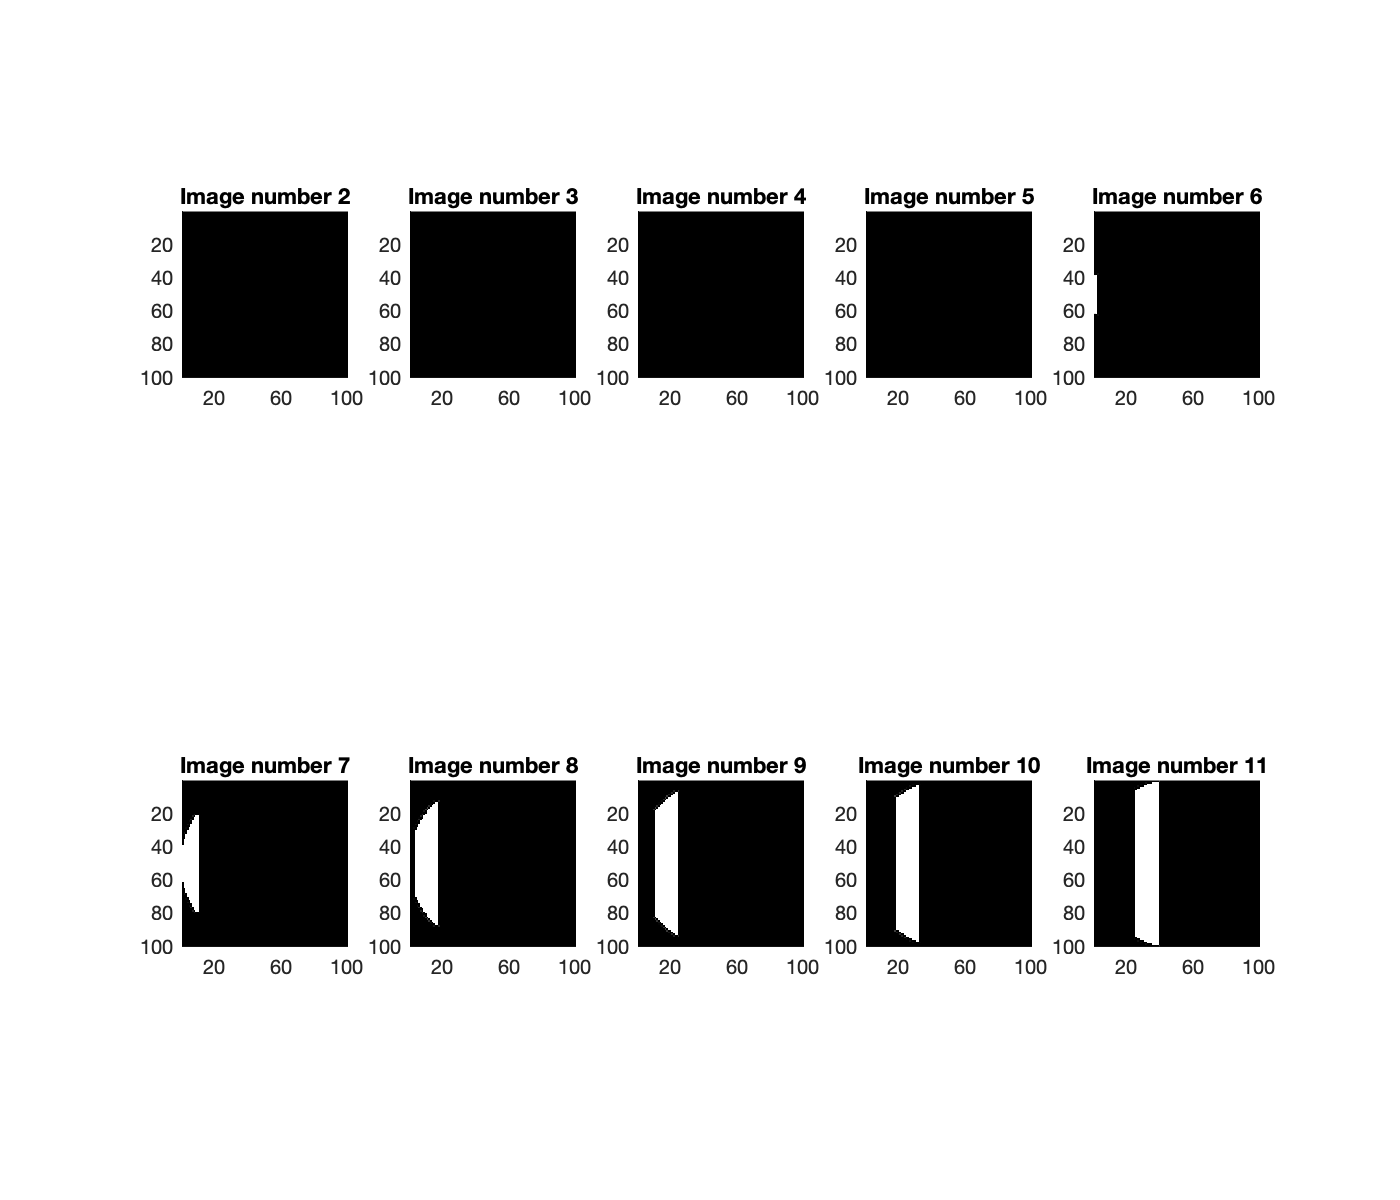

% Check BCBL dataset now
figure;
set(gcf,'Units','points','Position',[100 100 700 600]);
for p=1:10
    subplot(2,5,p); hold on;
    num = 1+1*p;
    imagesc(stimulusbcbl{1}(:,:,num),[0 1]);
    axis image tight;
    set(gca,'YDir','reverse');
    colormap(gray);
    title(sprintf('Image number %d',num));
end

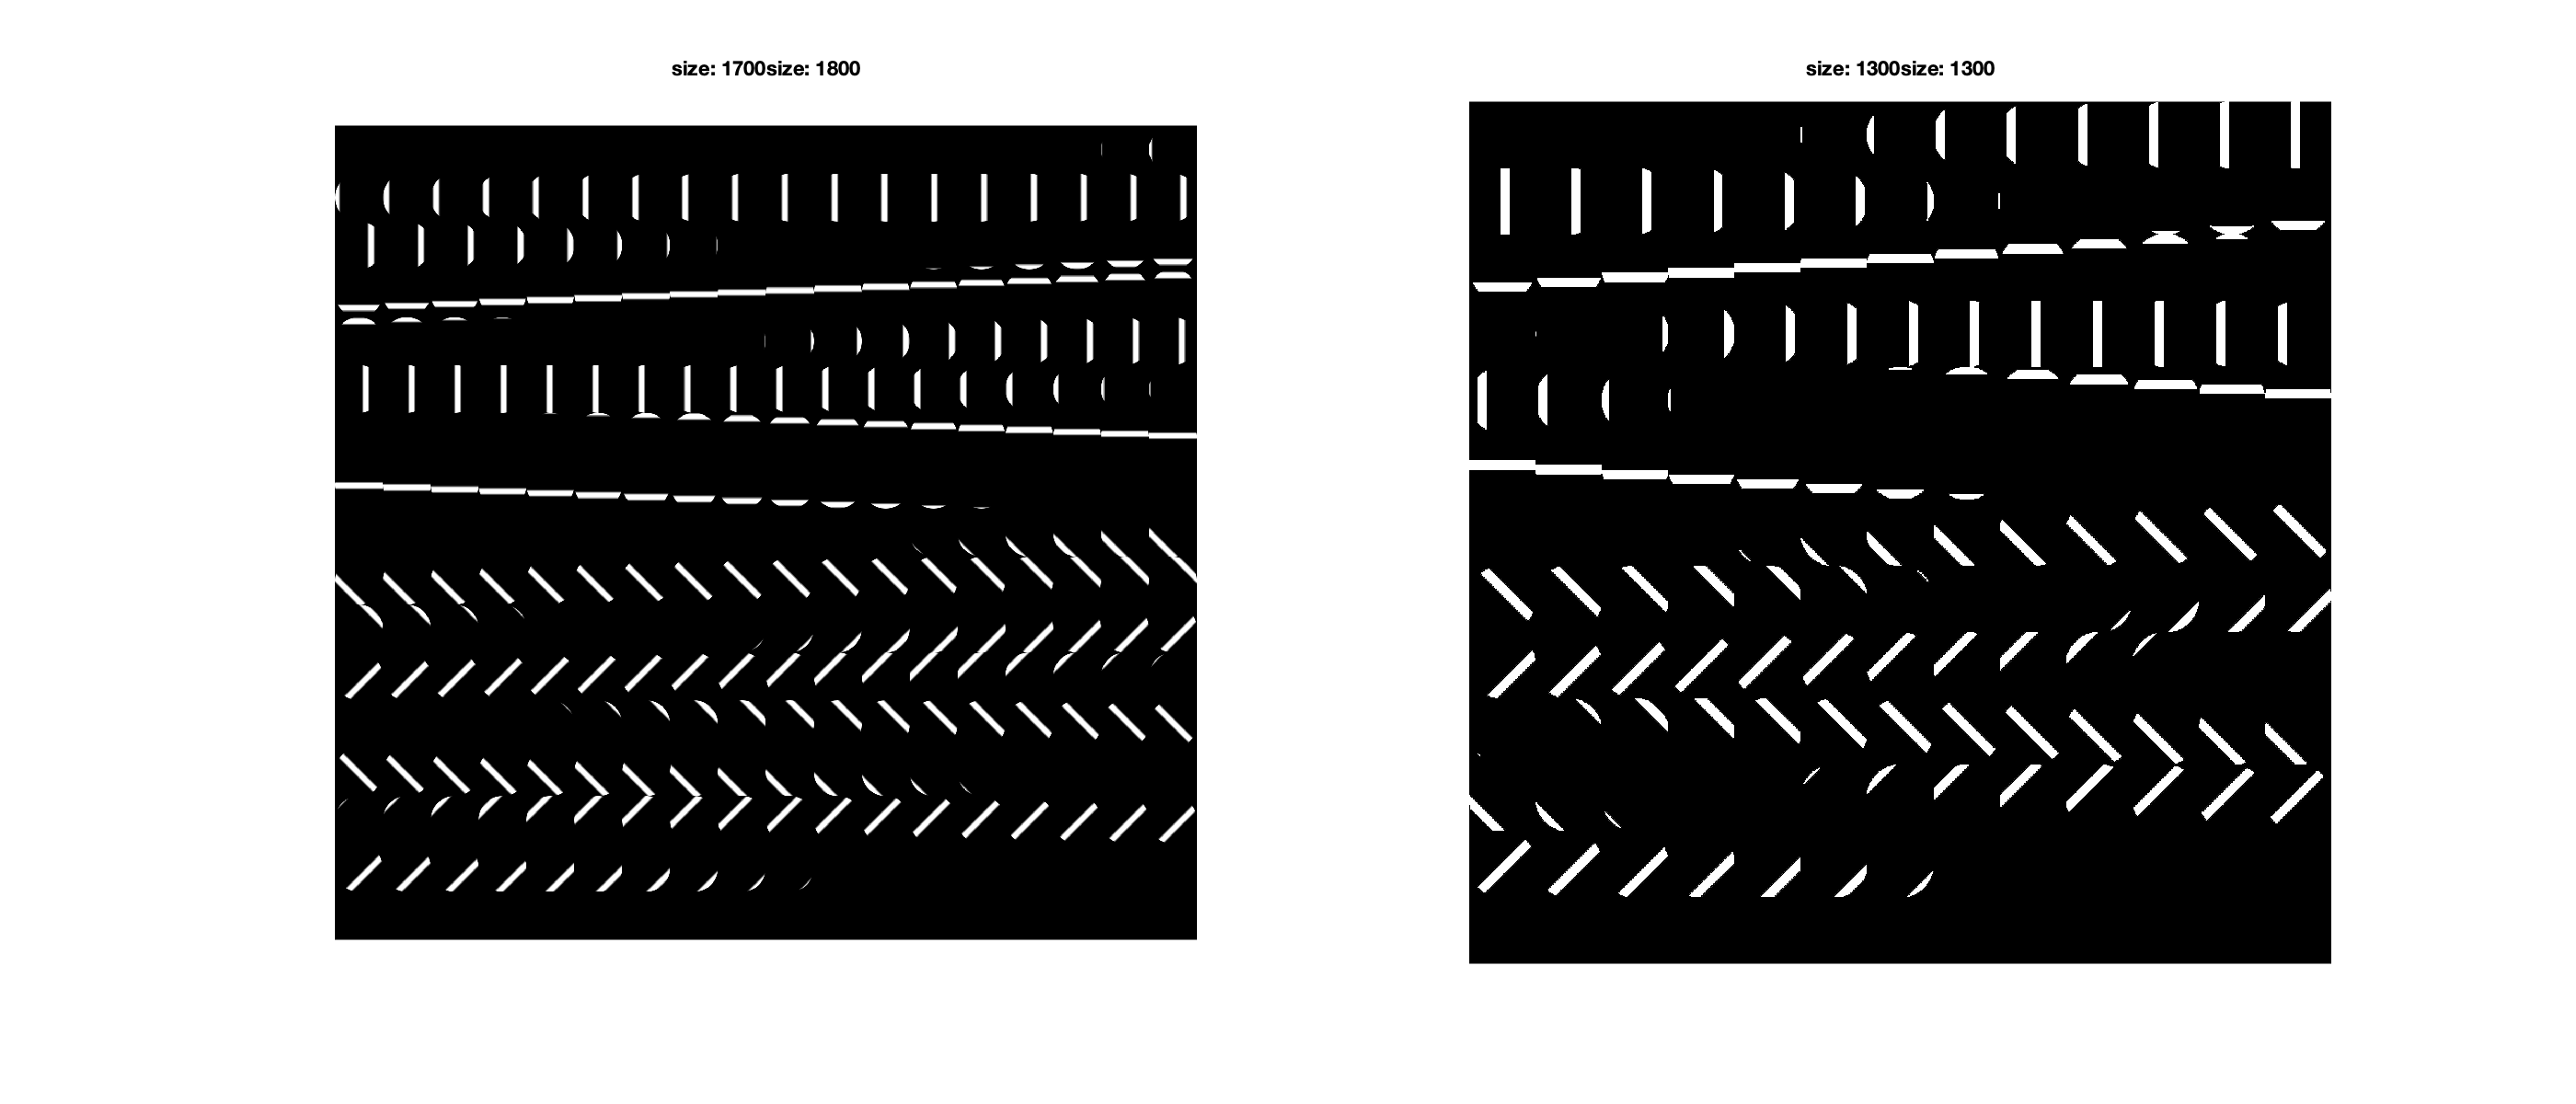


figure; 
set(gcf,'Units','points','Position',[100 100 1400 600]);
subplot(1,2,1)
img=makeMontage(stimulus{1});
imagesc(img); colormap(gray); axis equal; axis off;
title(sprintf('size: %i',size(img)))
subplot(1,2,2)
img=makeMontage(stimulusbcbl{1});
imagesc(img); colormap(gray); axis equal; axis off;
title(sprintf('size: %i',size(img)))

% Notice that the range of values is 0 to 1 (0 indicates that the gray background was
% present; 1 indicates that the stimulus was present).  For these stimulus images,
% the stimulus is a bar that moves downward and to the left.

## Analyze the data

% We need to resample the data to match the temporal rate of the stimulus.  Here we use
% cubic interpolation to increase the rate of the data from 2 seconds to 1 second (note
% that the first time point is preserved and the total data duration stays the same).
dataI = tseriesinterp(data,2,1,2);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 6 workers.



% Finally, we analyze the data using analyzePRF.  The third argument is the TR, which
% is now 1 second.  The default analysis strategy involves two generic initial seeds
% and an initial seed that is computed by performing a grid search.  This last seed is
% a little costly to compute, so to save time, we set 'seedmode' to [0 1] which means
% to just use the two generic initial seeds.  We suppress command-window output by
% setting 'display' to 'off'.

dataI = cellfun(@(x) (double(x)), dataI, 'UniformOutput',0);
stimulus = cellfun(@(x) (double(x)), stimulus, 'UniformOutput',0);

results = analyzePRF(stimulus,dataI,1,struct('seedmode',[0 1],'display','off','wantglmdenoise',true));

*** analyzePRF: started at 08-May-2019 12:45:05. ***
using the following maximum polynomial degrees: [3 3 3 3]
*** fitnonlinearmodel: started at 08-May-2019 12:45:06. ***
*** fitnonlinearmodel: loading data. ***
*** fitnonlinearmodel: outputdir = , chunksize = 10, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 10). ***
  starting resampling case 1 of 1.
    trying seed 1 of 2.
      for model 1 of 2, the seed is [50.500 50.500 17.678 10.000 0.500 ].
      the estimated parameters are [52.485 74.906 6.104 88.928 0.500 ].
      for model 2 of 2, the seed is [52.485 74.906 6.104 88.928 0.500 ].
      the estimated parameters are [52.459 74.840 6.618 91.228 0.548 ].
    trying seed 2 of 2.
      for model 1 of 2, the seed is [50.500 50.500 1.768 10.000 0.500 ].
      the estimated parameters are [55.751 80.696 12.749 -4.616 0.500 ].
      for model 2 of 2, the seed is [55.751 80.696 12.749 -4.616 0.500 ].
      the estimated parameters are [55.751 80.696 12.749 -4.616 0.500 ]

% Do the same with bcbl data
resultsbcbl = analyzePRF(stimulusbcbl,databcbl,1.82,struct('seedmode',[0 1],'display','off'));

*** analyzePRF: started at 08-May-2019 13:04:47. ***
using the following maximum polynomial degrees: [2 2 2]
*** fitnonlinearmodel: started at 08-May-2019 13:04:48. ***
*** fitnonlinearmodel: loading data. ***
*** fitnonlinearmodel: outputdir = , chunksize = 10, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 10). ***
  starting resampling case 1 of 1.
    trying seed 1 of 2.
      for model 1 of 2, the seed is [50.500 50.500 17.678 10.000 0.500 ].
      the estimated parameters are [56.854 83.711 -5.502 143.934 0.500 ].
      for model 2 of 2, the seed is [56.854 83.711 -5.502 143.934 0.500 ].
      the estimated parameters are [56.721 83.477 -2.633 117.993 0.160 ].
    trying seed 2 of 2.
      for model 1 of 2, the seed is [50.500 50.500 1.768 10.000 0.500 ].
      the estimated parameters are [56.851 83.713 -5.496 143.947 0.500 ].
      for model 2 of 2, the seed is [56.851 83.713 -5.496 143.947 0.500 ].
      the estimated parameters are [56.721 83.477 -2.634 118.018 

% Note that because of the use of parfor, the command-window output for different
% voxels may come in at different times (and so the text above is not really
% readable).

## Inspect the results

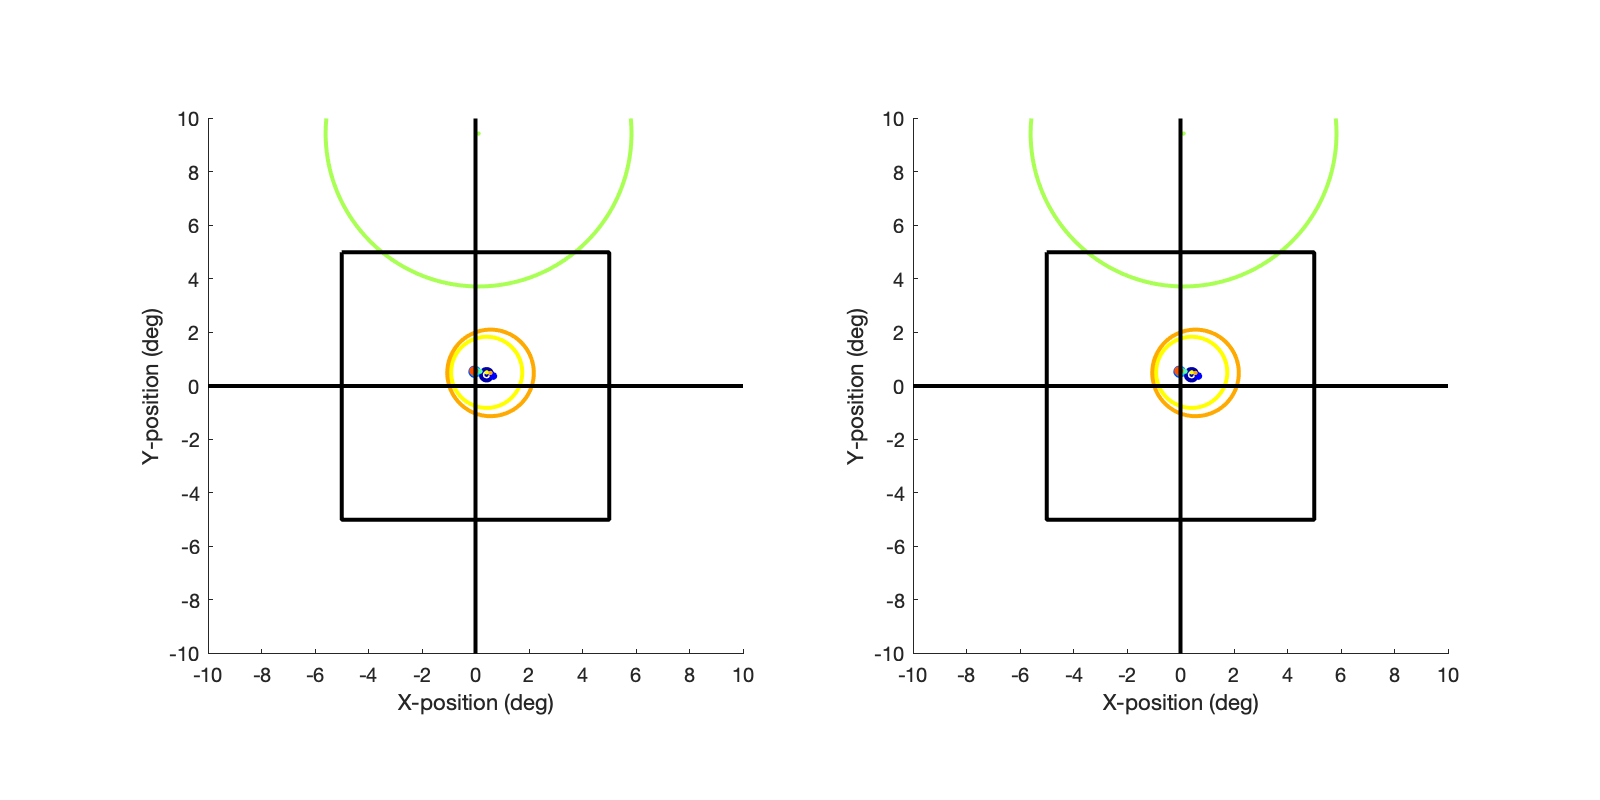

% The stimulus is 100 pixels (in both height and weight), and this corresponds to
% 10 degrees of visual angle.  To convert from pixels to degreees, we multiply
% by 10/100.
cfactor     = 10/100;
cfactorbcbl = 10/100;


% Visualize the location of each voxel's pRF
figure; hold on;
set(gcf,'Units','points','Position',[100 100 800 400]);

% Plot their results
subplot(1,2,1)
cmap = jet(size(results.ang,1));
for p=1:size(results.ang,1)
    xpos = results.ecc(p) * cos(results.ang(p)/180*pi) * cfactor;
    ypos = results.ecc(p) * sin(results.ang(p)/180*pi) * cfactor;
    ang = results.ang(p)/180*pi;
    sd = results.rfsize(p) * cfactor;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
end
drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
axis([-10 10 -10 10]);
straightline(0,'h','k-');       % line indicating horizontal meridian
straightline(0,'v','k-');       % line indicating vertical meridian
axis square;
set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
xlabel('X-position (deg)');
ylabel('Y-position (deg)');
% Plot bcbl results
subplot(1,2,2)
cmap = jet(size(resultsbcbl.ang,1));
for p=1:size(resultsbcbl.ang,1)
    xpos = resultsbcbl.ecc(p) * cos(resultsbcbl.ang(p)/180*pi) * cfactorbcbl;
    ypos = resultsbcbl.ecc(p) * sin(resultsbcbl.ang(p)/180*pi) * cfactorbcbl;
    ang = resultsbcbl.ang(p)/180*pi;
    sd = resultsbcbl.rfsize(p) * cfactorbcbl;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
end
drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
axis([-10 10 -10 10]);
straightline(0,'h','k-');       % line indicating horizontal meridian
straightline(0,'v','k-');       % line indicating vertical meridian
axis square;
set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
xlabel('X-position (deg)');
ylabel('Y-position (deg)');

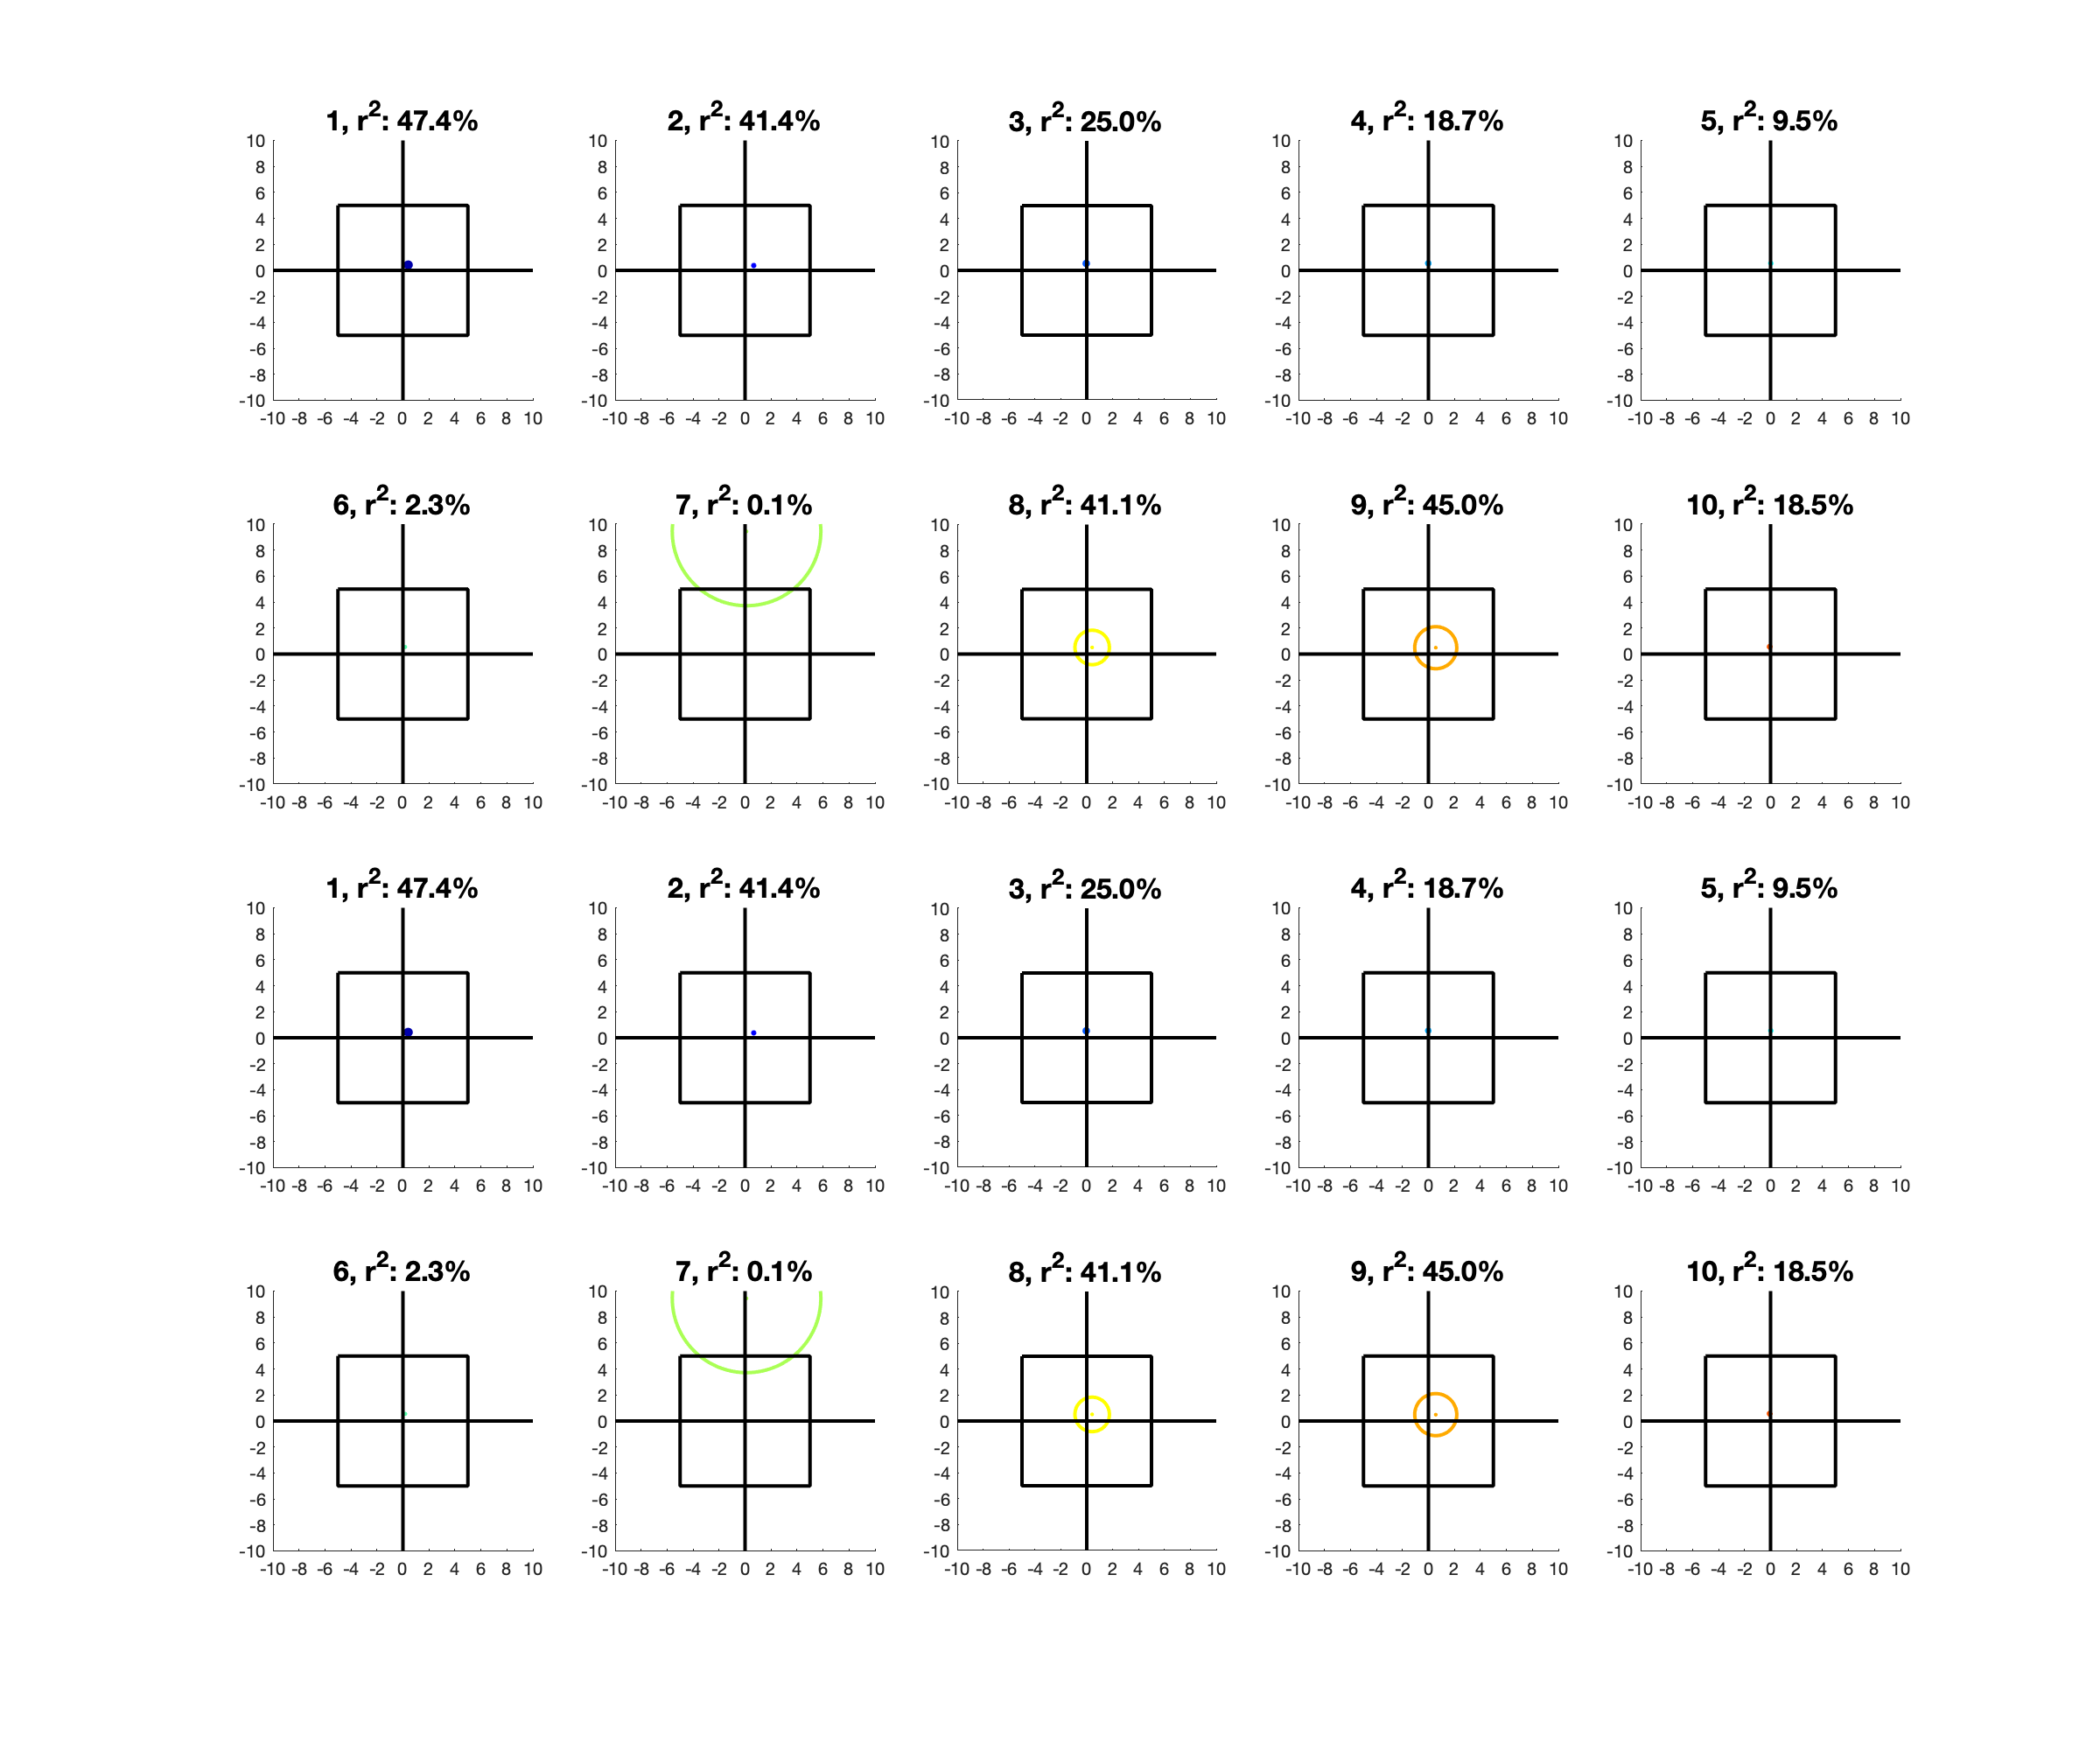

% Visualize the location of each voxel's pRF in a separate subplot
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1200 1000]);


cmap = jet(size(results.ang,1));
for p=1:size(results.ang,1)
    subplot(4,5,p)
    xpos = results.ecc(p) * cos(results.ang(p)/180*pi) * cfactor;
    ypos = results.ecc(p) * sin(results.ang(p)/180*pi) * cfactor;
    ang = results.ang(p)/180*pi;
    sd = results.rfsize(p) * cfactor;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
    drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
    axis([-10 10 -10 10]);
    straightline(0,'h','k-');       % line indicating horizontal meridian
    straightline(0,'v','k-');       % line indicating vertical meridian
    axis square;
    set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
    %xlabel('X-position (deg)');
    %ylabel('Y-position (deg)');
    title(sprintf('%d, r^2: %3.1f%%', p, results.R2(p)), 'FontSize', 16);
end
cmap = jet(size(resultsbcbl.ang,1));
howManyP = p;
for p=1:size(resultsbcbl.ang,1)
    subplot(4,5,howManyP+p)
    xpos = resultsbcbl.ecc(p) * cos(resultsbcbl.ang(p)/180*pi) * cfactorbcbl;
    ypos = resultsbcbl.ecc(p) * sin(resultsbcbl.ang(p)/180*pi) * cfactorbcbl;
    ang = resultsbcbl.ang(p)/180*pi;
    sd = resultsbcbl.rfsize(p) * cfactor;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
    drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
    axis([-10 10 -10 10]);
    straightline(0,'h','k-');       % line indicating horizontal meridian
    straightline(0,'v','k-');       % line indicating vertical meridian
    axis square;
    set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
    %xlabel('X-position (deg)');
    %ylabel('Y-position (deg)');
    title(sprintf('%d, r^2: %3.1f%%', p, resultsbcbl.R2(p)), 'FontSize', 16);
end

## Visualize the predicted and observed time series. First, some setup...

% Define some variables
res = [100 100];                    % row x column resolution of the stimuli
resmx = max(res);                   % maximum resolution (along any dimension)
hrf = results.options.hrf;          % HRF that was used in the model
degs = results.options.maxpolydeg;  % vector of maximum polynomial degrees used in the model

% Pre-compute cache for faster execution
[d,xx,yy] = makegaussian2d(resmx,2,2,2,2);

% Prepare the stimuli for use in the model
stimulusPP = {};
for p=1:length(stimulus)
  stimulusPP{p} = squish(stimulus{p},2)';  % this flattens the image so that the dimensionality is now frames x pixels
  stimulusPP{p} = [stimulusPP{p} p*ones(size(stimulusPP{p},1),1)];  % this adds a dummy column to indicate run breaks
end

% Define the model function.  This function takes parameters and stimuli as input and
% returns a predicted time-series as output.  Specifically, the variable <pp> is a vector
% of parameter values (1 x 5) and the variable <dd> is a matrix with the stimuli (frames x pixels).
% Although it looks complex, what the function does is pretty straightforward: construct a
% 2D Gaussian, crop it to <res>, compute the dot-product between the stimuli and the
% Gaussian, raise the result to an exponent, and then convolve the result with the HRF,
% taking care to not bleed over run boundaries.
modelfun = @(pp,dd) conv2run(posrect(pp(4)) * (dd*[vflatten(placematrix(zeros(res),makegaussian2d(resmx,pp(1),pp(2),abs(pp(3)),abs(pp(3)),xx,yy,0,0) / (2*pi*abs(pp(3))^2))); 0]) .^ posrect(pp(5)),hrf,dd(:,prod(res)+1));

% Construct projection matrices that fit and remove the polynomials.
% Note that a separate projection matrix is constructed for each run.
polymatrix = {};
for p=1:length(degs)
    % GLU: I think it is a bug, it needs to be dataI, not data
  polymatrix{p} = projectionmatrix(constructpolynomialmatrix(size(dataI{p},2),0:degs(p)));
end

Undefined variable "dataI" or class "dataI".

% BCBL
% Define some variables
res   = [100 100];                       % row x column resolution of the stimuli
resmx = max(res);                        % maximum resolution (along any dimension)
hrf   = resultsbcbl.options.hrf;         % HRF that was used in the model
degs  = resultsbcbl.options.maxpolydeg;  % vector of maximum polynomial degrees used in the model

% Pre-compute cache for faster execution
[d,xx,yy] = makegaussian2d(resmx,2,2,2,2);

% Prepare the stimuli for use in the model
stimulusPPbcbl = {};
for p=1:length(stimulusbcbl)
  stimulusPPbcbl{p} = squish(stimulusbcbl{p},2)';  % this flattens the image so that the dimensionality is now frames x pixels
  stimulusPPbcbl{p} = [stimulusPPbcbl{p} p*ones(size(stimulusPPbcbl{p},1),1)];  % this adds a dummy column to indicate run breaks
end

% Construct projection matrices that fit and remove the polynomials.
% Note that a separate projection matrix is constructed for each run.
polymatrixbcbl = {};
for p=1:length(degs)
  polymatrixbcbl{p} = projectionmatrix(constructpolynomialmatrix(size(databcbl{p},2),0:degs(p)));
end


## Inspect the data and the model fit

% Which voxel should we inspect?  Let's inspect the second voxel.
vx = 2;

% For each run, collect the data and the model fit.  We project out polynomials
% from both the data and the model fit.  This deals with the problem of
% slow trends in the data.
datats = {};
modelts = {};
% GLU: edited data for dataI
for p=1:length(dataI)
  datats{p} =  polymatrix{p} * dataI{p}(vx,:)';
  modelts{p} = polymatrix{p} * modelfun(results.params(1,:,vx),stimulusPP{p});
end

Index exceeds array bounds.


% Visualize the results
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1000 400]);
subplot(2,1,1)
plot(cat(1,datats{:}),'r-'); hold on;
plot(cat(1,modelts{:}),'b-');
straightline(300*(1:4)+.5,'v','g-');
xlabel('Time (s)');
ylabel('BOLD signal');
ax = axis;
axis([.5 1200+.5 ax(3:4)]);
title('Time-series data');

% Which voxel should we inspect?  
vx = 6;

% For each run, collect the data and the model fit.  We project out polynomials
% from both the data and the model fit.  This deals with the problem of
% slow trends in the data.
datats = {};
modelts = {};
for p=1:length(databcbl)
  datatsbcbl{p} =  polymatrixbcbl{p} * databcbl{p}(vx,:)';
  modeltsbcbl{p} = polymatrixbcbl{p} * modelfun(resultsbcbl.params(1,:,vx),stimulusPPbcbl{p});
end

% Visualize the results
subplot(2,1,2)
plot(cat(1,datatsbcbl{:}),'r-'); hold on;
plot(cat(1,modeltsbcbl{:}),'b-');
straightline(161*(1:3)+.5,'v','g-');
xlabel('Time (s)');
ylabel('BOLD signal');
ax = axis;
axis([.5 161*3+.5 ax(3:4)]);
title('Time-series data BCBL');

## Compare the prediction of the model to a different a temporally shuffled stimulus

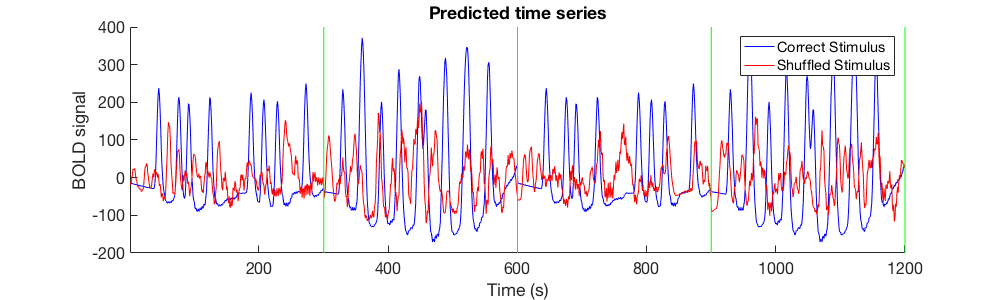

for p=1:length(data)
    n = size(data{p},2);
    idx = randperm(n);    
    modeltsShuffled{p} = polymatrix{p}*modelfun(results.params(1,:,vx),stimulusPP{p}(idx,:));
end

% Visualize the results
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1000 300]);
plot(cat(1,modelts{:}),'b-');
plot(cat(1,modeltsShuffled{:}),'r-');
straightline(300*(1:4)+.5,'v','g-');
xlabel('Time (s)');
ylabel('BOLD signal');
ax = axis;
axis([.5 1200+.5 ax(3:4)]);
legend('Correct Stimulus', 'Shuffled Stimulus')
title('Predicted time series');
set(gca, 'FontSize', 16)

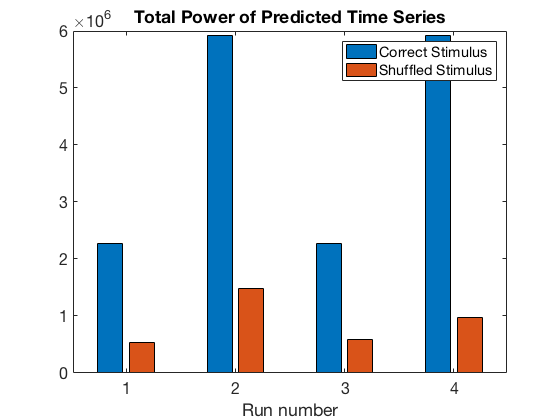


figure, bar(cellfun(@(x) sum(x.^2), [modelts; modeltsShuffled]'))
legend('Correct Stimulus', 'Shuffled Stimulus')
title('Total Power of Predicted Time Series')
xlabel('Run number')
set(gca, 'FontSize', 16)